# Taller Filtros - Parte 3

#### Ana Sofia Aponte Barriga

#### Daniel Esteban Prieto Jiménez

#### José Alejandro Peñaranda Chia

# Filtros FIR

Se cargan las variables requeridas:

fsAudio = 64000 ;
load Audio1.mat
load Audio2.mat
[Audio3, fsmp3] = audioread("jour-1.mp3") ; % Acá se cambia el mp3
Audio3 = Audio3(:, 1) ;

### Espacio para seleccionar el audio

prueba = Audio2 ;
fs = fsAudio ;

### Creación de los filtros

Inicialmente se calculará el orden de cada uno de los filtros.

fs=64000

fs = 64000

N1 = ceil((fs*15)/((250-125)*22))

N1 = 350

N2 = ceil((fs*15)/((125-62.5)*22))

N2 = 699

N3 = ceil((fs*15)/((500-250)*22))

N3 = 175

N4 = ceil((fs*15)/((2000-1000)*22))

N4 = 44

N5 = ceil((fs*15)/((8000-4000)*22))+1

N5 = 12

### El procedimiento para aplicar la funcion fir es definir cada una de las posibles ventanas a utilizar, para posteriormente, aplicar la funcion fir con esta ventana y la frecuencia de corte dividida entre pi.

se usaran 5 diferentes ventanas:

RECTANGULAR(R)

HAMMING(HM)

HANNING(HN)

BLACKMAN(BL)

BARTLETT(BA)

#### G1

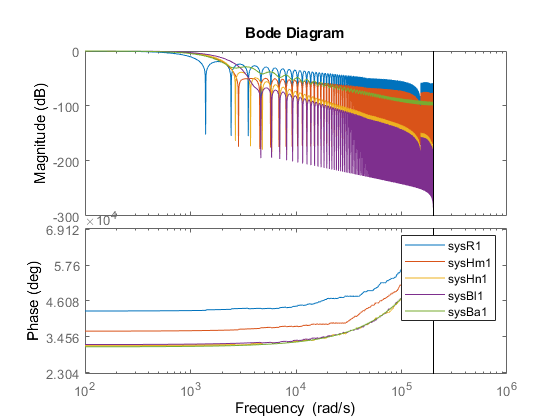

Wn1 = (2*pi*125)/fs ;
% ventanas
WR1 = ones(N1+1, 1) ;
WHn1 = hann(N1+1) ;
WBl1 = blackman(N1+1) ;
WBa1 = bartlett(N1+1) ;
% sistemas
BR1 = fir1(N1, Wn1/pi,'low', WR1);
sysR1 = tf(BR1, 1, 1/fs);
BHm1 = fir1(N1, Wn1/pi, 'low') ;
sysHm1 = tf(BHm1, 1, 1/fs);
BHn1 = fir1(N1, Wn1/pi, 'low', WHn1) ;
sysHn1 = tf(BHn1, 1, 1/fs);
BBl1 = fir1(N1, Wn1/pi, 'low', WBl1) ;
sysBl1 = tf(BBl1, 1, 1/fs);
BBa1 = fir1(N1, Wn1/pi, 'low', WBa1) ;
sysBa1 = tf(BBa1, 1, 1/fs);
bode(sysR1, sysHm1, sysHn1, sysBl1, sysBa1)
legend('sysR1', 'sysHm1', 'sysHn1', 'sysBl1', 'sysBa1')

Para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s.

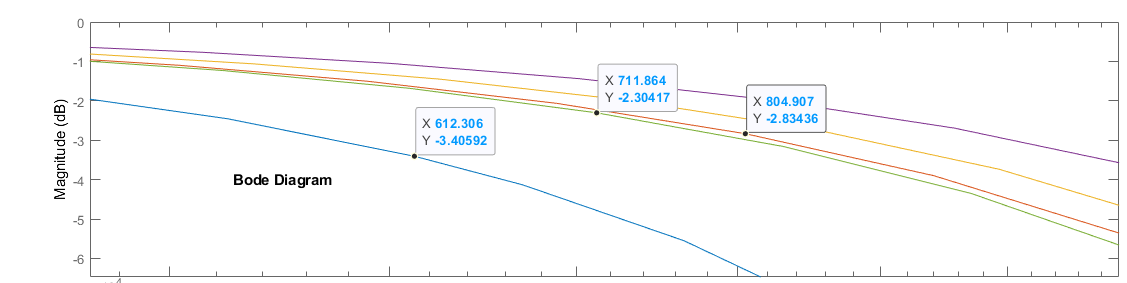

Elegimos la linea verde(BA), ya que es la que mas se aproxima al filtro deseado, esto lo podemos observar con la frecuecia de corte en 3dB.

#### G2

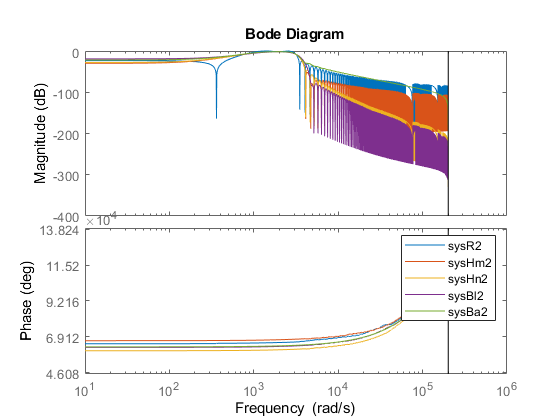

Wn2 = [(2*pi*125)/fs (2*pi*500)/fs];
% ventanas
WR2 = ones(N2+1, 1) ;
WHn2 = hann(N2+1) ;
WBl2 = blackman(N2+1) ;
WBa2 = bartlett(N2+1) ;
% sistemas
BR2 = fir1(N2, Wn2/pi,'bandpass', WR2);
sysR2 = tf(BR2, 1, 1/fs);
BHm2 = fir1(N2, Wn2/pi, 'bandpass') ;
sysHm2 = tf(BHm2, 1, 1/fs);
BHn2 = fir1(N2, Wn2/pi, 'bandpass', WHn2) ;
sysHn2 = tf(BHn2, 1, 1/fs);
BBl2 = fir1(N2, Wn2/pi, 'bandpass', WBl2) ;
sysBl2 = tf(BBl2, 1, 1/fs);
BBa2 = fir1(N2, Wn2/pi, 'bandpass', WBa2) ;
sysBa2 = tf(BBa2, 1, 1/fs);
bode(sysR2, sysHm2, sysHn2, sysBl2, sysBa2)
legend('sysR2', 'sysHm2', 'sysHn2', 'sysBl2', 'sysBa2')

 para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s y 500 Hz que equivale a 3141,6 rad/s.

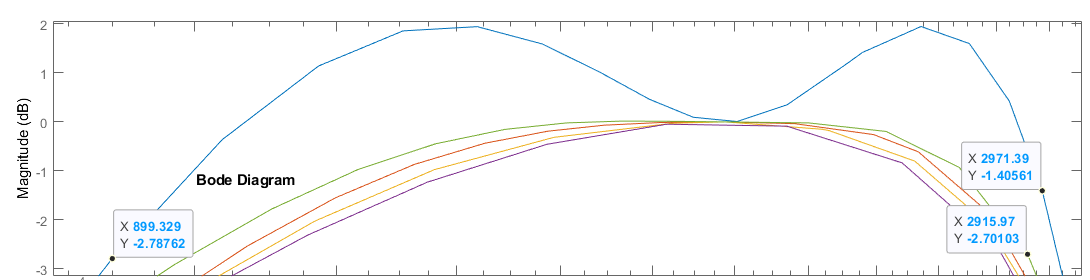

observamos que el filtro con frecuencia de corte más exactas es el azul(R), sin embargo, en las frecuencias intermedias presentan un sobre pico de hasta 2 dB por esta razón lo descartamos quedando el segundo mejor filtro que es el verde(BA).

#### G3

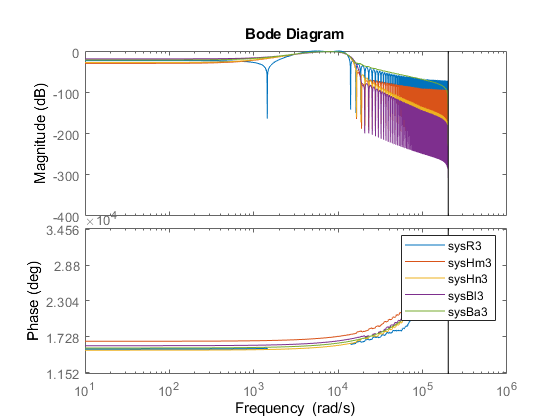

Wn3 = [(2*pi*500)/fs (2*pi*2000)/fs];
% ventanas
WR3 = ones(N3+1, 1) ;
WHn3 = hann(N3+1) ;
WBl3 = blackman(N3+1) ;
WBa3 = bartlett(N3+1) ;
% sistemas
BR3 = fir1(N3, Wn3/pi,'bandpass', WR3);
sysR3 = tf(BR3, 1, 1/fs);
BHm3 = fir1(N3, Wn3/pi, 'bandpass') ;
sysHm3 = tf(BHm3, 1, 1/fs);
BHn3 = fir1(N3, Wn3/pi, 'bandpass', WHn3) ;
sysHn3 = tf(BHn3, 1, 1/fs);
BBl3 = fir1(N3, Wn3/pi, 'bandpass', WBl3) ;
sysBl3 = tf(BBl3, 1, 1/fs);
BBa3 = fir1(N3, Wn3/pi, 'bandpass', WBa3) ;
sysBa3 = tf(BBa3, 1, 1/fs);
bode(sysR3, sysHm3, sysHn3, sysBl3, sysBa3)
legend('sysR3', 'sysHm3', 'sysHn3', 'sysBl3', 'sysBa3')

para este caso la frecuencia de corte es de 500 Hz lo que equivale a 3141,6 rad/s y 2000 Hz que equivale a 12566,4 rad/s.

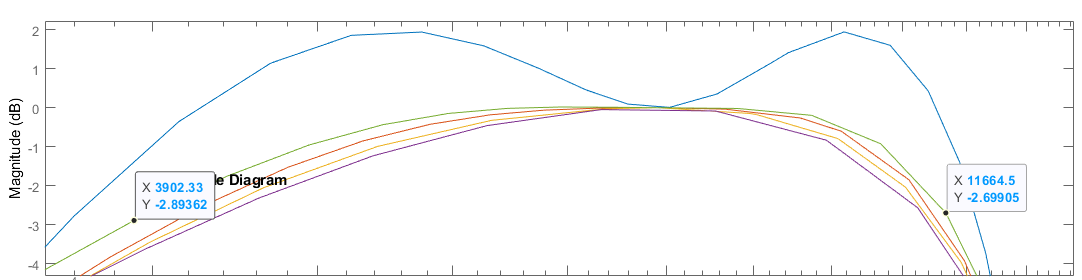

al igual que en el caso anterior el filtor azul(R) queda descartado por el sobre pico que presenta, quedando como seleccionado el verde(BA).

#### G4

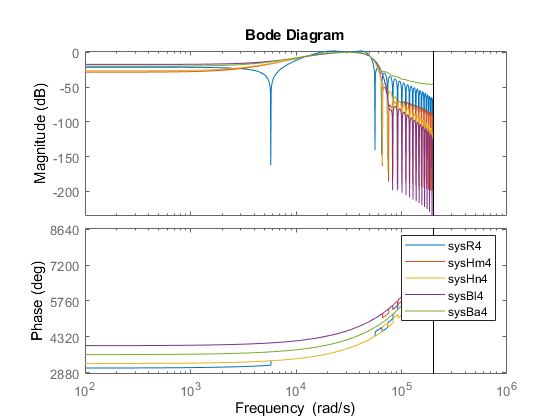

Wn4 = [(2*pi*2000)/fs (2*pi*8000)/fs];
% ventanas
WR4 = ones(N4+1, 1) ;
WHn4 = hann(N4+1) ;
WBl4 = blackman(N4+1) ;
WBa4 = bartlett(N4+1) ;
% sistemas
BR4 = fir1(N4, Wn4/pi,'bandpass', WR4);
sysR4 = tf(BR4, 1, 1/fs);
BHm4 = fir1(N4, Wn4/pi, 'bandpass') ;
sysHm4 = tf(BHm4, 1, 1/fs);
BHn4 = fir1(N4, Wn4/pi, 'bandpass', WHn4) ;
sysHn4 = tf(BHn4, 1, 1/fs);
BBl4 = fir1(N4, Wn4/pi, 'bandpass', WBl4) ;
sysBl4 = tf(BBl4, 1, 1/fs);
BBa4 = fir1(N4, Wn4/pi, 'bandpass', WBa4) ;
sysBa4 = tf(BBa4, 1, 1/fs);
bode(sysR4, sysHm4, sysHn4, sysBl4, sysBa4)
legend('sysR4', 'sysHm4', 'sysHn4', 'sysBl4', 'sysBa4')

para este caso la frecuencia de corte es de 2000 Hz que equivale a 12566,4 rad/s y 8000 Hz que equivale a 50265,5 rad/s.

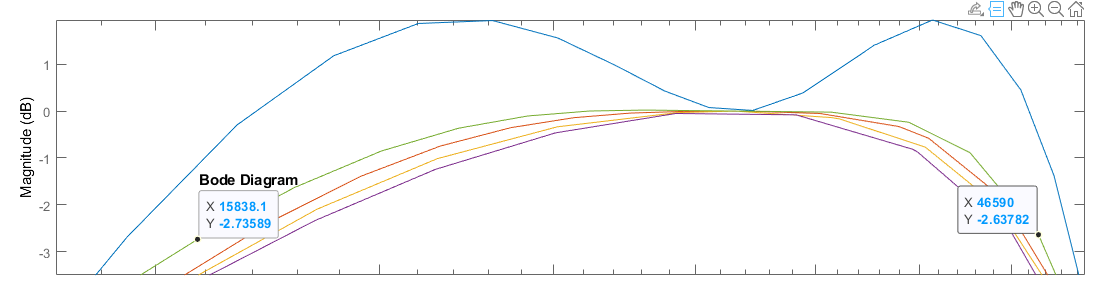

al igual que los dos caos pasados el filtro azul(R) es el que mas se aproxima al filtro deseado, pero tiene el inconveniente de la amplificacion, por esta razon se selecciona el segundo mejor filtro el verde(BA).

#### G5

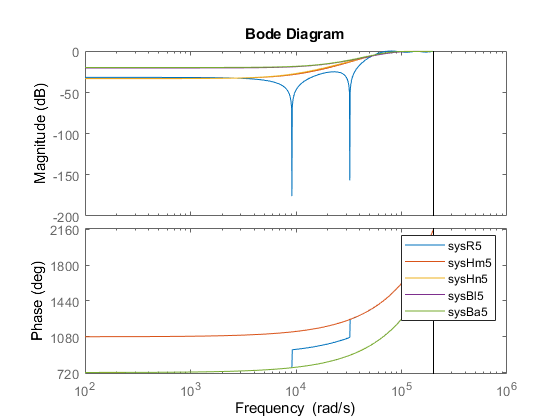

Wn5 = (2*pi*8000)/fs;
% ventanas
WR5 = ones(N5+1, 1) ;
WHn5 = hann(N5+1) ;
WBl5 = blackman(N5+1) ;
WBa5 = bartlett(N5+1) ;
% sistemas
BR5 = fir1(N5, Wn5/pi,'high', WR5);
sysR5 = tf(BR5, 1, 1/fs);
BHm5 = fir1(N5, Wn5/pi, 'high') ;
sysHm5 = tf(BHm5, 1, 1/fs);
BHn5 = fir1(N5, Wn5/pi, 'high', WHn5) ;
sysHn5 = tf(BHn5, 1, 1/fs);
BBl5 = fir1(N5, Wn5/pi, 'high', WBl5) ;
sysBl5 = tf(BBl5, 1, 1/fs);
BBa5 = fir1(N5, Wn5/pi, 'high', WBa5) ;
sysBa5 = tf(BBa5, 1, 1/fs);
bode(sysR5, sysHm5, sysHn5, sysBl5, sysBa5)
legend('sysR5', 'sysHm5', 'sysHn5', 'sysBl5', 'sysBa5')

para este caso la frecuencia de corte es de 8000 Hz que equivale a 50265,5 rad/s.

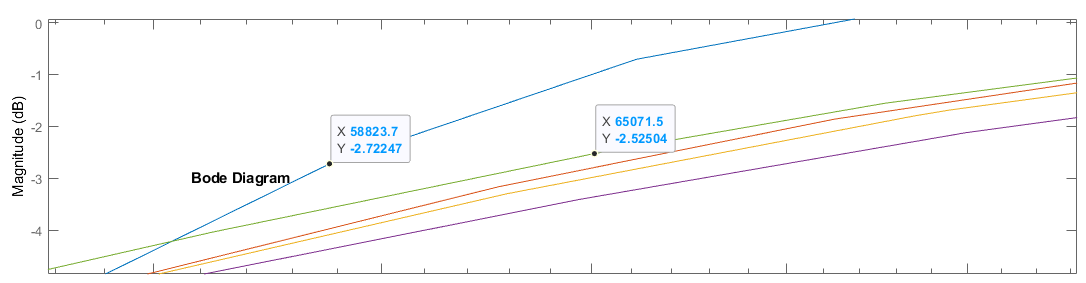

para este caso el mejor filtro es el azul(R), ya que tiene la atenuacion de 3 dB cerca al valor deseado de frecuencia.

Se plotea la parte inicial de la señal de entrada para tener una idea más clara de la forma de esta:

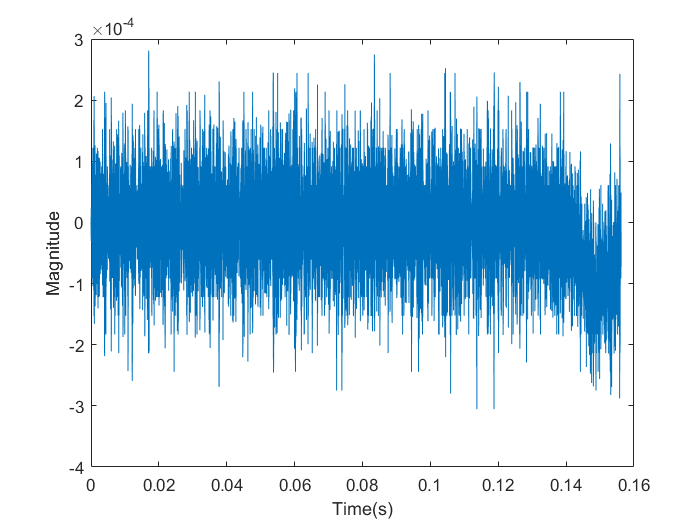

len = size(prueba, 1) ;
T = linspace(0, ceil(len/fs), len)' ;
plot(T(1:10000, 1), prueba(1:10000, 1))
xlabel('Time(s)')
ylabel('Magnitude')

En el caso de los archivos de prueba Audio1 y Audio2 la frecuencia de muestreo es 64000 y la longitud del vector de entrada es 640000 entonces el tiempo total será:


$$T=\frac{640000}{64000}=10\;s$$


el vector T tiene la misma longitud del vector de audio.

### Implementación de los filtros

Se crea un sistema con cada filtro y se aplica a la señal de entrada:

#### G1

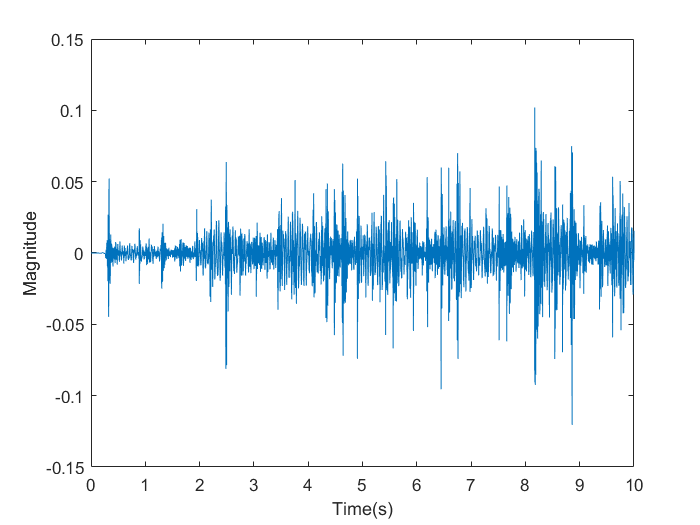

y1 = fftfilt(BBa1, prueba);
plot(T, y1)
xlabel('Time(s)')
ylabel('Magnitude')

#### G2

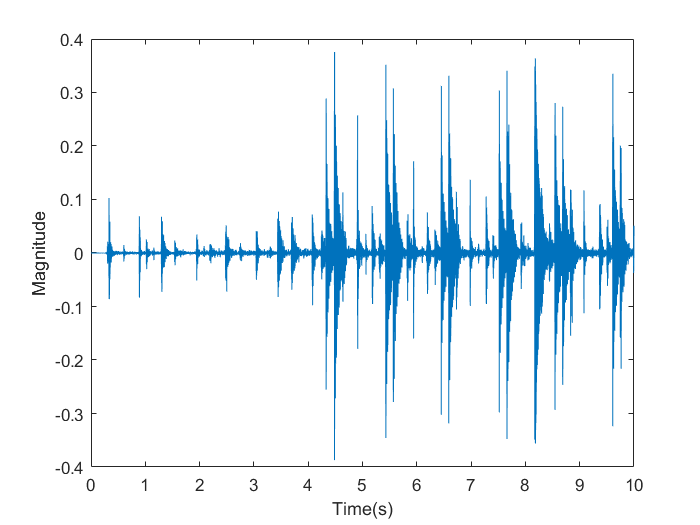

y2 = fftfilt(BBa2, prueba);
plot(T, y2)
xlabel('Time(s)')
ylabel('Magnitude')

#### G3

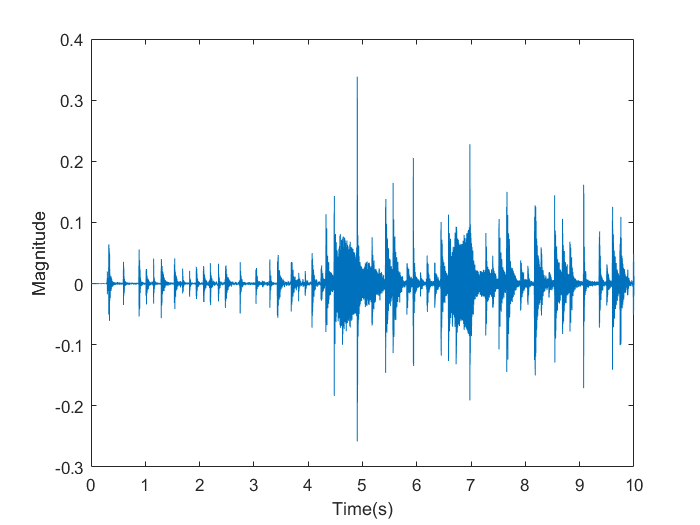

y3 = fftfilt(BBa3, prueba);
plot(T, y3)
xlabel('Time(s)')
ylabel('Magnitude')

#### G4

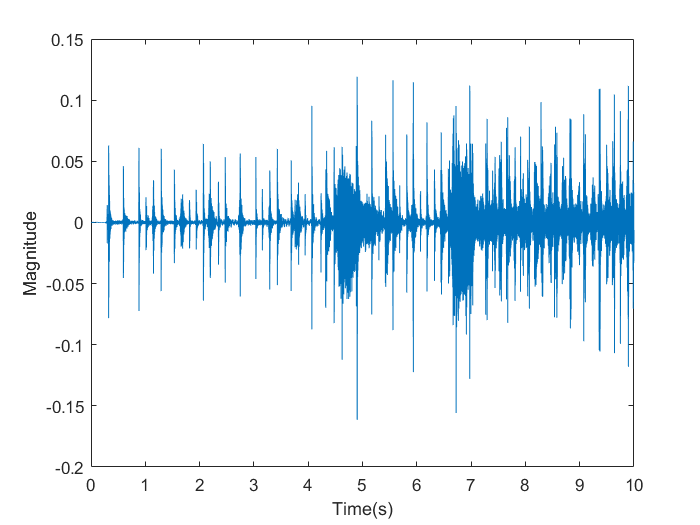

y4 = fftfilt(BBa4, prueba);
plot(T, y4)
xlabel('Time(s)')
ylabel('Magnitude')

#### G5

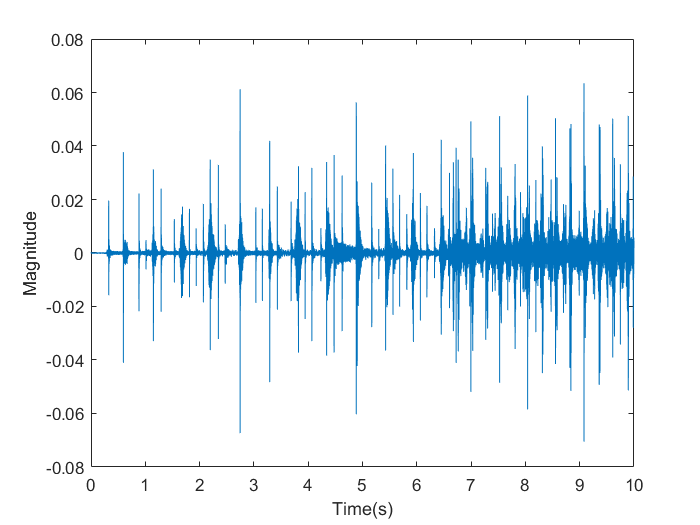

y5 = fftfilt(BR5, prueba);
plot(T, y5)
xlabel('Time(s)')
ylabel('Magnitude')

#### Ganancias

Finalmente se eligen los valores de las ganancias para combinar las señales de salida de los filtros:

G1 = 1; % 62.5Hz
G2 = 1; % 250Hz
G3 = 1; % 1kHz
G4 = 1; % 4kHz
G5 = 1; % 16kHz
 

  G1 = 1 ; G2 = 1 ; G3 = 1 ; G4 = 1 ; G5 = 1 ;

  G1 = 1 ; G2 = 1 ; G3 = 1.3 ; G4 = 0.6 ; G5 = 0.6 ;

  G1 = 1 ; G2 = 0.4 ; G3 = 1.1 ; G4 = 1.6 ; G5 = 1.6 ;

  G1 = 1 ; G2 = 1.5 ; G3 = 0.8 ; G4 = 0.9 ; G5 = 0.9 ;

  G1 = 1 ; G2 = 1.3 ; G3 = 0.8 ; G4 = 1.3 ; G5 = 1.3 ;

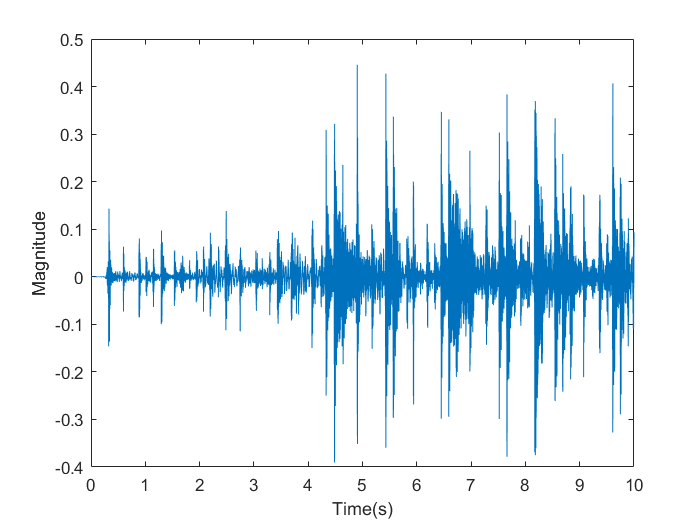

 
Y = G1*y1+G2*y2+G3*y3+G4*y4+G5*y5 ;
plot(T, Y)
xlabel('Time(s)')
ylabel('Magnitude')

 
if max(abs(Y)) > 1
    Y = Y/max(abs(Y)) ;
end
player = audioplayer(Y, fs)

player =   audioplayer with properties:

       SampleRate: 64000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 640000
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


play(player)

  stop(player) 